# Laboratório de Controle - Aula 3 - 2022/1

## Introdução ao Matlab e Simulink para simulação de sistemas dinâmicos

## **Nome**: 

**Objetivo desta aula: fazer simulações de um sistema de dois tanques acoplados usando modelos lineares, não lineares e discretos**

**IMPORTANTE: usar Run Section para fazer as atividades e Run para gerar o relatório final a ser entregue.**

**Assista o **[video](https://drive.google.com/file/d/19driAsOHd4eocl21ymD8392NvW7RTHjG/view?usp=sharing)** sobre esta aula.**

turma=0;
I=0;
[h10,h20,q,a1,a2]=init(turma,I)
Ar=pi*12.5^2;
datetime('now')
pwd
tic

**Sistema de dois tanques acoplados**

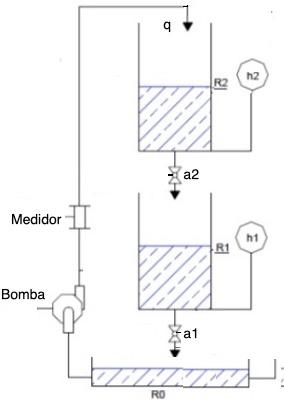

A bomba produz uma vazão $q$ no reservatório superior R2, que desce para R1 através da válvula manual $a_2$. A água de R1 escoa para R0 através da válvula manual $a_1$.

Equações que regem seu comportamento:


$$\frac{dh_1}{dt}=-\frac{a_1}{A}\sqrt{2gh_1}+\frac{a_2}{A}\sqrt{2gh_2}$$



$$\frac{dh_2}{dt}=-\frac{a_2}{A}\sqrt{2gh_2}+\frac{100}{6A}q$$


Vazão q em $l/min$

Nível em $cm$

Gravidade $g=981\frac{cm}{s^2}$

Área dos tanques $A=\pi 12.5^2   cm^2$

 Ponto de operação do sistema:

Os dois níveis se estabilizam quando a vazão que passa por $a_1$ é igual a que passa por $a_2$, sendo iguais a $q$. Os niveis $h_1$ e $h_2$ dependem dos valores de $a_1$ e $a_2$, respectivamente. Para obter o ponto de operação, basta fazer as derivadas iguais a zero.

O ponto de operação é definido pela vazão $q$ e pelos níveis $h_1$ e $h_2$, que por sua vez depende das aberturas $a_1$ e $a_2$, respectivamente.

Linearização:

Definindo:


$$u=q-q_0$$



$$x=h-h_0$$


$\dot{x}=\dot{h}$ (para o sistema não linear tem-se $h$ para representar o nível e para o sistema linear tem-se $x$).

e usando a expansão em séries de Taylor na parte não linear da equação de nível:


$$\frac{df(x,q)}{dx}=\frac{a_1\sqrt{2g}}{2\sqrt{x_0}}=a_1\sqrt{g/2x_0} $$


resultam as equações de $x_1(t)$ e $x_2(t)$ linearizadas em torno de $x_{10},x_{20},q_0$:


$$A\frac{dx_2}{dt}=\frac{100}{6}q-a_2\sqrt{\frac{g}{2x_{20}}}x_2$$



$$A\frac{dx_1}{dt}=-a_1\sqrt{\frac{g}{2x_{10}}}x_1+a_2\sqrt{\frac{g}{2x_{20}}}x_2$$


Destas equações pode-se obter o modelo em variáveis de estado


$$\dot{x}=Ax+Bu \\
y = Cx
$$


e o modelo por função de transferência 


$$\frac{Y(s)}{U(s)}=G(s)=C(sI-A)^1B$$


**Atividade 1: Simulação do sistema não linear**

*1.1 Simular o modelo não linear no Matlab para o ponto de operacão definido, e identificar seu ponto de operação, comentando o comportamento das curvas 3 e seus valores. Observe que a função "nivel_2tanques" contém exatamente as equações do modelo não linear.*

*function dh = nivel_2tanques(t,h,a1,a2,q)*

*g=981;*

*A=pi*12.5^2;*

*dh1=-(a1/A)*sqrt(2*g*h(1))+(a2/A)*sqrt(2*g*h(2));*

*dh2=-(a2/A)*sqrt(2*g*h(2))+(100/6)*q/A;*

*dh=[dh1;dh2];*

[t,h] = ode45(@(t,y) nivel_2tanques(t,y,a1,a2,q), [0 1000], [0.1;0.1]);
qr1=(6/100)*a1*sqrt(2*981*h(:,1));
figure;
plot(t,h,t,qr1);legend('h_1','h_2','q_{R1}');title('Figura 1: Simulação do sistema não-linear');

Resposta:

1.2 Mostre ao professor o resultado da simulação e obtenha com ele a simulação que deve ser feita neste item, explicando abaixo o que foi pedido e o resultado da análise.

*1.3 Refazer a simulação começando do ponto de operação e aumentando ou diminuindo um pouco a vazão q, variando dq, comentando o efeito sobre as curvas e seus valores.*

*Resposta:*

dq=0;
[t,h] = ode45(@(t,y) nivel_2tanques(t,y,a1,a2,q+dq), [0 1000], [h10;h20]);
qr1=(6/100)*a1*sqrt(2*981*h(:,1));
figure;
plot(t,h,t,qr1);legend('h_1','h_2','q_R1');
title('Figura 2: Simulação do sistema não-linear variando a vazão ');
xlabel('Tempo(s)')

**Atividade 2: Simulação do sistema linear**

No código a seguir, o sistema linearizado é representado em variáveis de estado por s1. 

A FT G é obtida considerando como saída apenas o nivel h1 de R1.

Aplica-se uma variação dq à vazão do ponto de operação q, ou seja, aplica-se uma vazão q+dq. Escolher o tempo de simulação adequado T1.

T1=0;
dq=0;
A=[-(a1/Ar)*sqrt(981/(2*h10))   (a2/Ar)*sqrt(981/(2*h20));0 -(a2/Ar)*sqrt(981/(2*h20))];
B=[0;100/(6*Ar)];
C=[1 0;0 1;(6/100)*a1*sqrt(981/(2*h10)) 0];
C0=[1 0];
D=[];
s1=ss(A,B,C,D);
s0=ss(A,B,C0,D);
G=tf(s0);
[x,t,z]=step(dq*s1,T1);
figure;
plot(t,x);legend('h_1','h_2','q_R1');
title('Figura 3: Simulação do sistema linear a um degrau dq de vazão');
xlabel('Tempo(s)')

2.1 Comentar as variações dos níveis e da vazão em torno do ponto de operação para o degrau aplicado.

Para comparar a resposta linear e não linear, deve-se somar o ponto de operação ao sistema linear, uma vez que sua simulação começa em zero. A função bsxfun soma o ponto de operação aos níveis e a vazão da simulação linear.

xnl=bsxfun(@plus,x,[h10 h20 q]);
[t1,h1] = ode45(@(t,y) nivel_2tanques(t,y,a1,a2,q+dq), [0 T1], [h10;h20]);
qr11=(6/100)*a1*sqrt(2*981*h1(:,1));
figure;
plot(t1,[h1 qr11],t,xnl);legend('h_1nl','h_2nl','q_R1nl','h_1l','h_2l','q_{R1}l')
title('Figura 4: Comparação dos sistemas linear não linear ao degrau dq');
xlabel('Tempo(s)')
erro_regime=100*xnl(end,1:2)./h1(end,1:2)
TOE=toc

2.2 Comparar a resposta do sistema linear e não linear variando a vazão aplicada via dq. Qual a máxima variação na vazão aplicada para que o erro em regime de $h_1$ e $h_2$ não passe de 2%?

2.3 Gere um modelo s1d discreto justificando a escolha do tempo de amostragem Ts. Plote então a resposta ao degrau dos sistemas continuos e discretos na mesma figura (step(s1,s1d)).

Justificativa para escolha de Ts;

**Atividade 3: Simulação dos dois tanques no simulink**

O diagrama mostrado é utilizado para simular o sistema de dois 2 tanques. Uma saturação é introduzida nos integradores de R1 e R2 para que o nível não passe de 100 cm, para uma simulação mais real.

Todos os parâmetros já definidos são utilizados no diagrama. Pode-se variar a vazão de entrada qs, escolhendo uma variação dqs. A simulação inicia no ponto de operação já definido.

3.1 Escolha um valor de dqs tal que apenas um dos reservatórios  chegue em 100cm. Comente as curvas e seus valores.

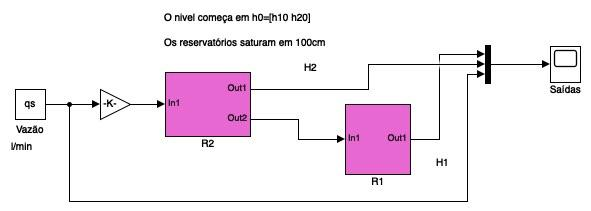

dqs=0;
qs=q+dqs;
[y2,t2]=simula_slx(T1);
figure;
plot(t2,y2);
legend('h_1nl','h_2nl','q')
title('Figura 5: Simulação do sistema não linear no simulink');
xlabel('Tempo(s)')

**Atividade 4: Avaliação dos modelos**

4.1 Verique os polos do sistema de dois tanques, informando se são reais ou complexos e se o sistema é estável, e por quê. Analise tanto o sistema contínuo quanto o discreto.

Caso contínuo:

Caso discreto:

4.2 Obtenha a função de transferência que relacione a vazão aplicada Q(s) com a vazão de saída do reservatório R2. Aplique então um degrau unitário na FT e explique o comportamento da saída.

Resposta: